# Proyecto Final de Algoritmos Numéricos por Computadora

## Modelado de los efectos de Plutón sobre la órbita de Neptuno

Realizado por: 

- Bernardo Padilla Fischer 182748

- Rodrigo Plauchú Rodríguez 182671

- Victor Hugo Castillejos Corzo 182344

## Identificación del problema

Se va a simular el comportamiento dinámico del sistema solar, considerando, únicamente, a los planetas y planetoides. Para eso, vamos a utilizar el modelo de fuerza de atracción entre masas numéricamente, utilizando las posiciones y velocidades de cada planeta para simular las órbitas de los planetas. Además, para predecir el movimiento de los planetas, se investigaron las posiciones actuales de 2018 y estas se usaron como posiciones iniciales. Es decir, un modelo de fuerza de atracción con 10 cuerpos. Por otro lado, utilizaremos el algoritmo RK4 para resolver las ecuaciones diferenciales del modelo físico que se presentan para resolver el problema. Por lo anterior, nos permite aproximar las posiciones reales de los cuerpos, con las influencias de las masas de los planetas. Además, se analizará y graficará la influencia que tiene Plutón sobre la órbita de Neptuno. Por último, la implementación será eficiente y agradable al ojo del lector. 

## Modelado matemático

El movimiento de los planetas en el sistema solar puede ser decrito, como se mencionó, por la teoría de la gravedad de Newton. Para el caso de dos cuerpos se tiene:


$$F=G\frac{m\;m^{\prime } }{r^3 }\mathit{\mathbf{r}}$$



$$\Rightarrow F=G\frac{m\;m^{\prime } }{r^3 }\left({\mathit{\mathbf{r}}}^{\prime } -\mathit{\mathbf{r}}\right)\;\;,{\;F}^{\prime } =G\frac{m\;m^{\prime } }{r^3 }\left(\mathit{\mathbf{r}}-{\mathit{\mathbf{r}}}^{\prime } \right)$$



$$\textrm{donde}\;m\;\textrm{es}\;\textrm{la}\;\textrm{masa},r\;\textrm{el}\;\textrm{vector}\;\textrm{de}\;\textrm{posición}\;y\;G\;\textrm{la}\;\textrm{constante}\;\textrm{de}\;\textrm{gravitación}\;\textrm{universal}\ldotp$$


Por lo tanto, para el caso del sistema solar con 10 cuerpos (el Sol, 8 planetas y un planeta enano: Plutón) se tiene:


$$\begin{array}{l}
\Rightarrow F_i =G{\cdot m}_i \sum_{j\not= i} \left\lbrace \frac{m_j }{r_{\mathrm{ij}}^3 }\left({\mathit{\mathbf{r}}}_{\mathbf{ji}} \right)\right\rbrace \\
\mathrm{con}\;{\mathit{\mathbf{r}}}_{\mathbf{ji}} ={\mathit{\mathbf{r}}}_{\mathit{\mathbf{j}}} -{\mathit{\mathbf{r}}}_{\mathit{\mathbf{i}}} =-{\mathit{\mathbf{r}}}_{\mathbf{ij}} \;\mathrm{el}\;\mathrm{vector}\;\mathrm{que}\;\mathrm{va}\;\mathrm{del}\;\mathrm{cuerpo}\;j\;\mathrm{al}\;\mathrm{cuerpo}\;i
\end{array}$$


Utilizando la segunda ley de Newton $\left(F=m\cdot a\right)$ se obtiene:


$$\Rightarrow {r^{\prime } }^{\prime } =a=\frac{F}{m}$$



$$\Rightarrow {{r_i }^{\prime } }^{\prime } =\frac{F_i }{m_i }=G\sum_{j\not= i} \left\lbrace \frac{m_j }{r_{\textrm{ij}}^3 }\left({\mathit{\mathbf{r}}}_{\textrm{ji}} \right)\right\rbrace$$



$$\Rightarrow {r_i }^{\prime } =v_i$$



$$\Rightarrow {v_i }^{\prime } ={{r_i }^{\prime } }^{\prime } =G\sum_{j\not= i} \left\lbrace \frac{m_j }{r_{\textrm{ij}}^3 }\left({\mathit{\mathbf{r}}}_{\textrm{ji}} \right)\right\rbrace$$


Usemos $\mathit{\mathbf{y}}=\left\lbrack \begin{array}{c}
\mathit{\mathbf{r}}\\
\mathit{\mathbf{v}}
\end{array}\right\rbrack$ para expresar el sistema de ecuaciones ${\mathit{\mathbf{y}}}^{\prime } =\left\lbrack \begin{array}{c}
\mathit{\mathbf{v}}\\
\mathit{\mathbf{a}}
\end{array}\right\rbrack$


$$\Rightarrow \frac{\mathrm{d}}{\mathrm{d}t}y=f\left(t,y\right)=f\left(t,\left\lbrack \mathit{\mathbf{r}},\mathit{\mathbf{v}}\right\rbrack \right)=\left\lbrack \begin{array}{c}
\mathit{\mathbf{v}}\\
\mathit{\mathbf{a}}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\mathit{\mathbf{v}}\\
G\left\lbrack \begin{array}{c}
\sum_{j\not= 1} \left\lbrace \frac{m_j }{r_{1,j}^3 }\left({\mathit{\mathbf{r}}}_{\mathit{\mathbf{j}},1} \right)\right\rbrace \\
\vdots \\
\sum_{j\not= 10} \left\lbrace \frac{m_j }{r_{10,j}^3 }\left({\mathit{\mathbf{r}}}_{\mathit{\mathbf{j}},10} \right)\right\rbrace 
\end{array}\right\rbrack 
\end{array}\right\rbrack$$


## Implementación

Aquí se establecen las masas, posiciones y velocidades de cada planeta y el Sol.

global G m;

G = 6.67428E-11;    %constante gravitacional

mSol=1.98854E+30;   %masa del Sol
mMerc=3.30200E+23;  %masa de Mercurio
mVenu=4.86850E+24;  %masa de Venus
mEart=5.97219E+24;  %masa de Tierra
mMars=6.41850E+23;  %masa de Marte
mJupi=1.89813E+27;  %masa de Jupiter
mSatu=5.68319E+26;  %masa de Saturno
mUran=8.68103E+25;  %masa de Urano
mNept=1.02410E+26;  %masa de Neptuno
mPlut=1.30700E+22;  %masa de Plutón

m=[mSol;mMerc;mVenu;mEart;mMars;mJupi;mSatu;mUran;mNept;mPlut];   %vector de masas

r0Sol=[1.81899E+08;9.83630E+08;-1.58778E+07];   %posicion inicial del Sol
r0Merc=[-5.67576E+10;-2.73592E+10;2.89173E+09]; %posicion inicial de Mercurio
r0Venu=[4.28480E+10;1.00073E+11;-1.11872E+09];  %posicion inicial de Venus
r0Eart=[-1.43778E+11;-4.00067E+10;-1.38875E+07];    %posicion inicial de Tierra
r0Mars=[-1.14746E+11;-1.96294E+11;-1.32908E+09];    %posicion inicial de Marte
r0Jupi=[-5.66899E+11;-5.77495E+11;1.50755E+10]; %posicion inicial de Jupiter
r0Satu=[8.20513E+10;-1.50241E+12;2.28565E+10];  %posicion inicial de Saturno
r0Uran=[2.62506E+12;1.40273E+12;-2.87982E+10];  %posicion inicial de Urano
r0Nept=[4.30300E+12;-1.24223E+12;-7.35857E+10]; %posicion inicial de Neptuno
r0Plut=[1.65554E+12;-4.73503E+12;2.77962E+10];  %posicion inicial de Plutón

r0=[r0Sol;r0Merc;r0Venu;r0Eart;r0Mars;r0Jupi;r0Satu;r0Uran;r0Nept;r0Plut]; %vector de posiciones iniciales
r1=[r0Sol;r0Nept;r0Plut];

v0Sol=[-1.12474E+01;7.54876E+00;2.68723E-01];   %velocidad inicial del Sol
v0Merc=[1.16497E+04;-4.14793E+04;-4.45952E+03]; %velocidad inicial de Mercurio
v0Venu=[-3.22930E+04;1.36960E+04;2.05091E+03];  %velocidad inicial de Venus
v0Eart=[7.65151E+03;-2.87514E+04;2.08354E+00];  %velocidad inicial de Tierra
v0Mars=[2.18369E+04;-1.01132E+04;-7.47957E+02]; %velocidad inicial de Marte
v0Jupi=[9.16793E+03;-8.53244E+03;-1.69767E+02]; %velocidad inicial de Jupiter
v0Satu=[9.11312E+03;4.96372E+02;-3.71643E+02];  %velocidad inicial de Saturno
v0Uran=[-3.25937E+03;5.68878E+03;6.32569E+01];  %velocidad inicial de Urano
v0Nept=[1.47132E+03;5.25363E+03;-1.42701E+02];  %velocidad inicial de Neptuno
v0Plut=[5.24541E+03;6.38510E+02;-1.60709E+03];  %velocidad inicial de Plutón

v0=[v0Sol;v0Merc;v0Venu;v0Eart;v0Mars;v0Jupi;v0Satu;v0Uran;v0Nept;v0Plut]; %vector de velocidades iniciales
v1=[v0Sol;v0Nept;v0Plut];

Se grafican las órbitas de cada planeta y el Sol en conjunto. Para esto tomamos los vectores que armamos y le aplicamos una función para resolver un sistema de segundo orden. Elegimos el método RK4 ya que ha mostrado un buen desempeño en la ejecución.

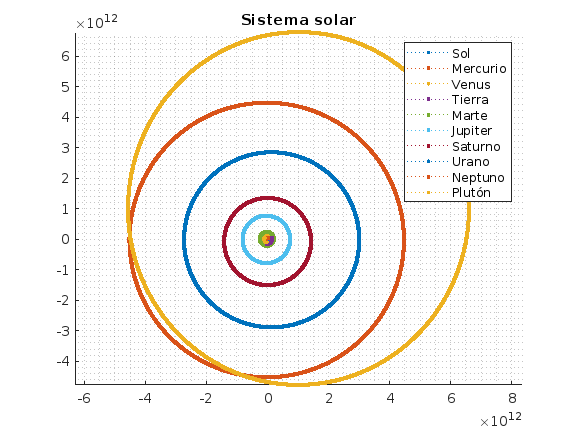

t0=0; tf=90560*24*60*60;    %periodo orbital de Pluto 248.109 años 
h=60*60*6; %periodo de 6 horas para cada lectura
fhandle=@f;
y0=[r0;v0];     %vector de posiciones y velocidades iniciales
[t,y]=odeRK4(fhandle,y0,t0,tf,h);

figure
hold on
for i=1:10
    %plot3-D
    plot3(y(3*i-2,:),y(3*i-1,:),y(3*i,:),':.')
end
hold off
grid minor
title('Sistema solar')
legend('Sol','Mercurio','Venus','Tierra','Marte','Jupiter','Saturno','Urano','Neptuno','Plutón')
axis equal

Se gráfican únicamente las órbitas del Sol, Neptuno y Plutón. Esto para poder visualizar de mejor manera el efecto que se discutirá más adelante de las órbitas de Neptuno y Plutón.

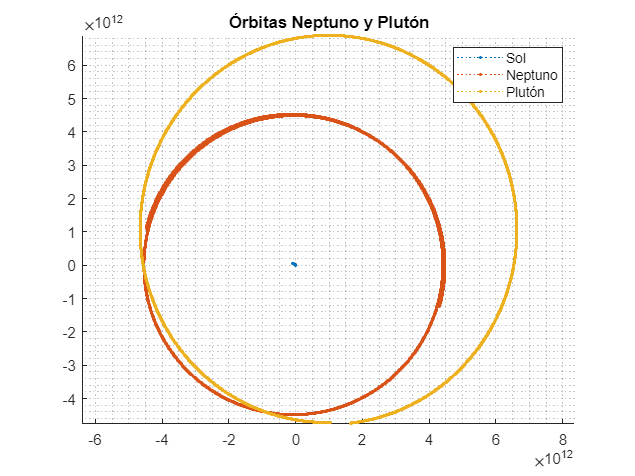

y0=[r1;v1];
[t1,y1]=odeRK4(fhandle,y0,t0,tf,h);

figure
hold on
for i=1:3
    %plot3-D
    plot3(y1(3*i-2,:),y1(3*i-1,:),y1(3*i,:),':.')
end
hold off
grid minor
title('Órbitas Neptuno y Plutón')
legend('Sol','Neptuno','Plutón')
axis equal

Como se puede apreciar en la gráfica, los efectos de Plutón sobre la órbita de Neptuno, hace que Neptuno se mueva con un movimiento elíptico irregular. Es decir, hace una trayectoria infinita que se recorre con cada vuelta. Esto se puede apreciar en la trayectoria roja. Un fenómeno interesante es el siguiente: las órbitas se intersectan. Por lo tanto, hay una pequeña probabilidad que ambos planetas choquen entre sí. Sin embargo, por el deplazamiento de la órbita de Neptuno, puede que los planetas nunca se encuentren porque el movimiento orbital de Neptuno hace que las órbitas se separen cada vez, únicamente, si la órbita de Neptuno sigue la tendencia mostrada en la gráfica.  

Oscilación entre la distancia de los planetas y el origen. Para realizar estos cálculos tenemos que obtener la información de los resultados de la función RK4 que utilizamos con anterioridad.

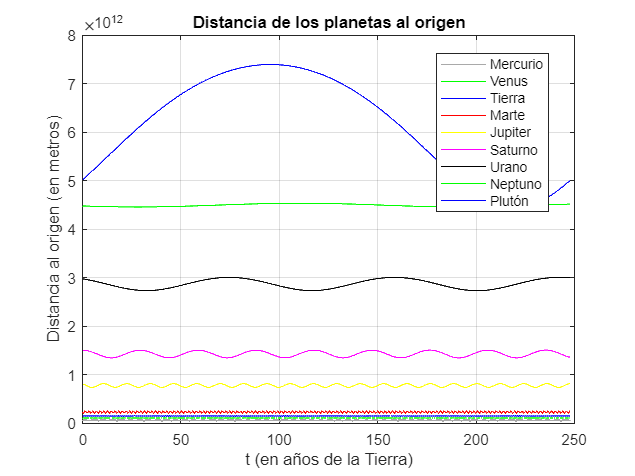

rInner=y(4:30,:);
dMerc=sqrt(rInner(1,:).^2+rInner(2,:).^2+rInner(3,:).^2);
dVenu=sqrt(rInner(4,:).^2+rInner(5,:).^2+rInner(6,:).^2);
dEart=sqrt(rInner(7,:).^2+rInner(8,:).^2+rInner(9,:).^2);
dMars=sqrt(rInner(10,:).^2+rInner(11,:).^2+rInner(12,:).^2);
dJupi=sqrt(rInner(13,:).^2+rInner(14,:).^2+rInner(15,:).^2);
dSat=sqrt(rInner(16,:).^2+rInner(17,:).^2+rInner(18,:).^2);
dUru=sqrt(rInner(19,:).^2+rInner(20,:).^2+rInner(21,:).^2);
dNep=sqrt(rInner(22,:).^2+rInner(23,:).^2+rInner(24,:).^2);
dPlut=sqrt(rInner(25,:).^2+rInner(26,:).^2+rInner(27,:).^2);
tYears=t/(60*60*24*365.25);

plot(tYears,dMerc,'color','#A9A9A9')
hold on
plot(tYears,dVenu,'g')
plot(tYears,dEart,'b')
plot(tYears,dMars,'r')
plot(tYears,dJupi,'y')
plot(tYears,dSat,'m')
plot(tYears,dUru,'k')
plot(tYears,dNep,'g')
plot(tYears,dPlut,'b')
hold off
grid on
xlabel('t (en años de la Tierra)')
ylabel('Distancia al origen (en metros)')
title('Distancia de los planetas al origen')
legend('Mercurio','Venus','Tierra','Marte','Jupiter','Saturno','Urano','Neptuno','Plutón','location',"best")

Oscilación de de la distancia de Neptuno y Plutón con respecto al origen. En esta gráfica se nota un efecto muy interesante y nos empieza a dar una noción de los efectos de Neptuno y Plutón en sus órbitas. Espor eso que segmentamos a solo estos 2 planetas de la gráfica anterior.

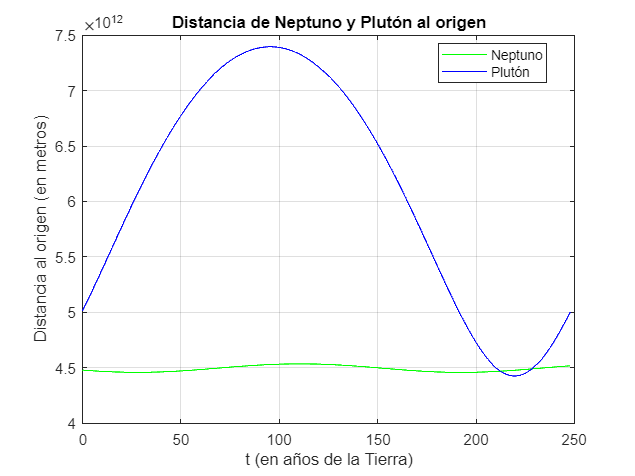

plot(tYears,dNep,'g')
hold on
plot(tYears,dPlut,'b')
hold off
grid on
xlabel('t (en años de la Tierra)')
ylabel('Distancia al origen (en metros)')
title('Distancia de Neptuno y Plutón al origen')
legend('Neptuno','Plutón','location',"best")

Finalmente, no nos olvidemos del sol, ya que es la referencia que podemos decir "absoluta" para todos los planetas. Esto, obviamnete porque todos los planetas de la vía láctea orbitan alrededor de este. Es por eso que resulta muy interesante observar la distancia que tiene el sol al origen. 

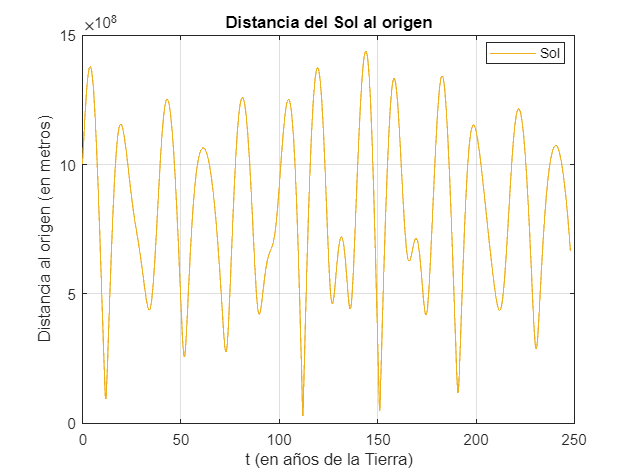

rSun=y(1:3,:);
dSun=sqrt(rSun(1,:).^2+rSun(2,:).^2+rSun(3,:).^2);
plot(tYears,dSun,"Color",'#EDB120')
grid on
xlabel('t (en años de la Tierra)')
ylabel('Distancia al origen (en metros)')
title('Distancia del Sol al origen')
legend('Sol','location',"best")

## Implementación de los requerimientos para la solución

function dy = f(~,y) %función que sigue el modelo matemático arriba descrito
    global G m;
    n=length(y)/2;
    r = y(1:n);    %vector de posicion
    v = y(n+1:end);   %vector de velocidad
    c=length(r)/3;
    rji=zeros(3,c,c);
    for i=1:c
        rf=r(3*i-2:3*i);
        for j=1:c
            rji(:,j,i)=r(3*j-2:3*j)-rf;
        end
    end   
    r3=sqrt(rji(1,:,:).^2+rji(2,:,:).^2+rji(3,:,:).^2).^3;
    a=zeros(c*3,1);
    for i=1:c
        a(3*i-2:3*i)=rji(:,[1:i-1 i+1:c],i)*(m([1:i-1 i+1:c])./r3(1,[1:i-1 i+1:c],i)');
    end
    a=G*a;
    dy=[v;a];
end

function [t,y]=odeRK4(f,y0,t0,tf,h) %el conocido RK4
    t=t0:h:tf;
    n=length(t);
    m=length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    for i=1:n-1
        k1=f(t(i),y(:,i));
        k2=f(t(i)+0.5*h,y(:,i)+0.5*k1*h);
        k3=f(t(i)+0.5*h,y(:,i)+0.5*k2*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end
end